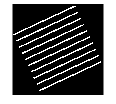

img = imread("Image1a.tif");

imshow(img);

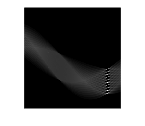


[H, teta, ro] = hough(img,'Rhoresolution', 5, 'Theta', -90:0.5:89.5);
H1 = ((H-min(H(:)))/max(H(:))-min(H(:)));
imshow(H1);

teta

teta =   -90.0000  -89.5000  -89.0000  -88.5000  -88.0000  -87.5000  -87.0000  -86.5000  -86.0000  -85.5000  -85.0000  -84.5000  -84.0000  -83.5000  -83.0000  -82.5000  -82.0000  -81.5000  -81.0000  -80.5000  -80.0000  -79.5000  -79.0000  -78.5000  -78.0000  -77.5000  -77.0000  -76.5000  -76.0000  -75.5000  -75.0000  -74.5000  -74.0000  -73.5000  -73.0000  -72.5000  -72.0000  -71.5000  -71.0000  -70.5000  -70.0000  -69.5000  -69.0000  -68.5000  -68.0000  -67.5000  -67.0000  -66.5000  -66.0000  -65.5000



[r,t] = find(H1==max(H1(:)));
teta(t)

ans =     65    65


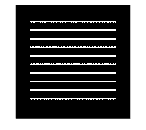


Image1a_rotated = imrotate(img,-25,'bicubic','crop');
imshow(Image1a_rotated);

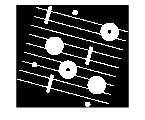

Image1b = imread("Image1b.tif");

imshow(Image1b);

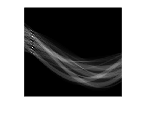


[H, teta, ro] = hough(Image1b,'Rhoresolution', 5, 'Theta', -90:0.5:89.5);
H2 = ((H-min(H(:)))/max(H(:))-min(H(:)));
imshow(H2);


[r,t] = find(H2==max(H2(:)));
teta(t)

ans = -75

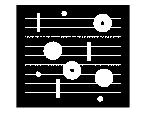


Image1b_rotated = imrotate(Image1b, 15, 'bicubic', 'crop');
imshow(Image1b_rotated);

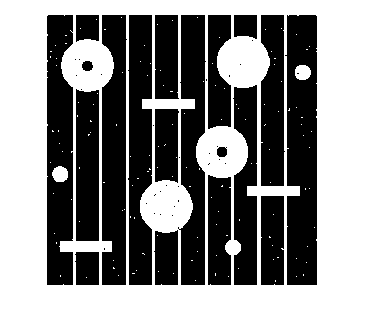

% Morphology
Image1c = imread("Image1c.tif");

imshow(Image1c);

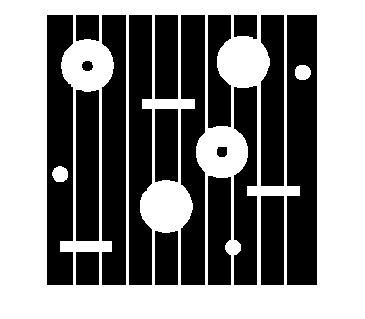


SE = strel('disk', 3);
IM2 = imopen(Image1c, SE);
Image1c_noiserem = imclose(IM2, SE);
imshow(Image1c_noiserem);

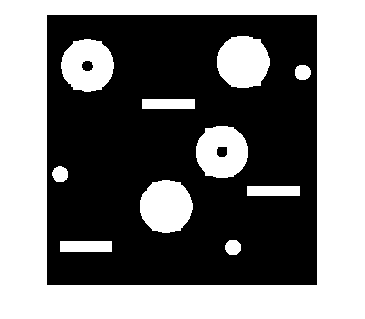


SE2 = strel('line',6, 0);
Image1c_clean = imopen(Image1c_noiserem, SE2);
imshow(Image1c_clean);

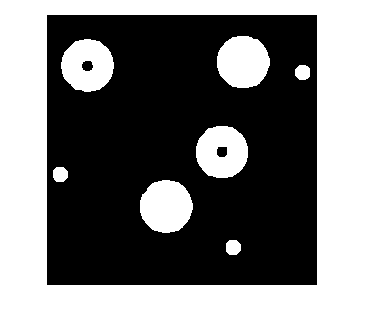


SE3 =strel('disk',13);
Image1c_disks = imopen(Image1c_clean, SE3);
imshow(Image1c_disks);

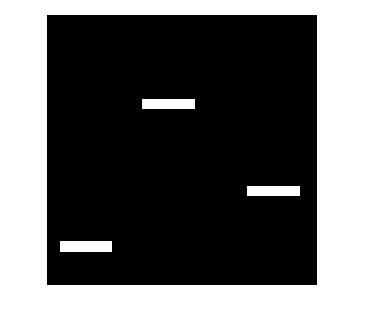


SE4=strel("rectangle", [20 100]);
Image1c_rect = imopen(Image1c_clean,SE4);
imshow(Image1c_rect);

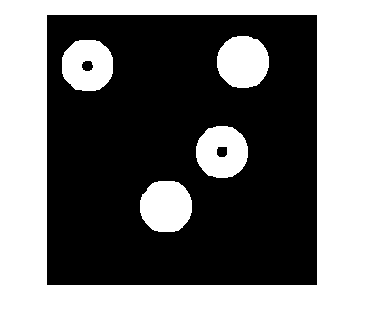


SE5 = strel("disk",14);
Image1c_largedisks = imopen(Image1c_clean, SE5);
imshow(Image1c_largedisks);

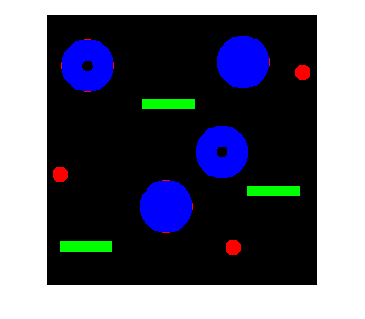


[r,c] = size(Image1c);
RGB = zeros(r,c,3);

RGB(:,:,1) = (Image1c_disks - Image1c_largedisks);
RGB(:,:,2) = Image1c_rect;
RGB(:,:,3) = Image1c_largedisks;
imshow(RGB);

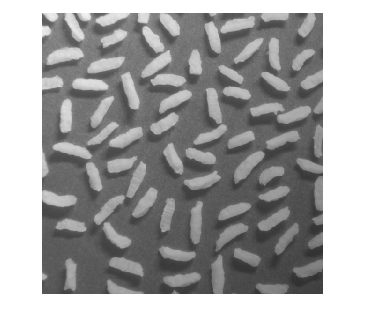

% Grayscale morphology
RiceImg = imread("rice-shaded.tif");
imshow(RiceImg);

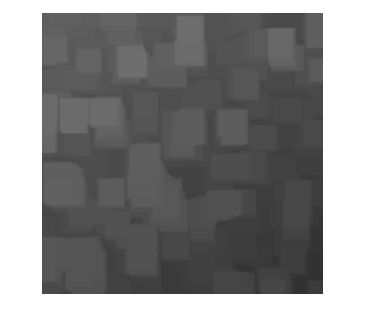


SE = strel("square",50);

RiceSeg = imopen(RiceImg,SE);
imshow(RiceSeg);

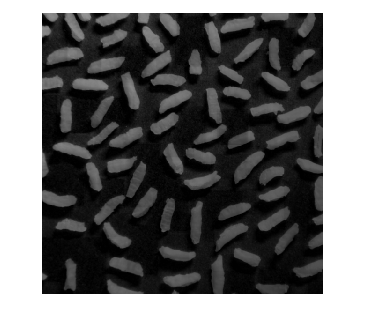


RiceNoShade = RiceImg - RiceSeg;
imshow(RiceNoShade);

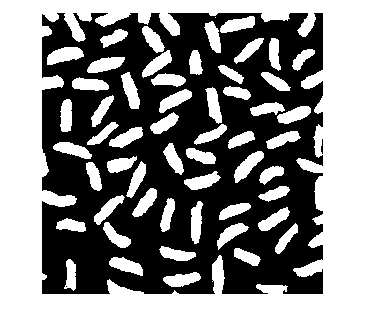


RiceBin = 50 < RiceNoShade;
imshow(RiceBin);

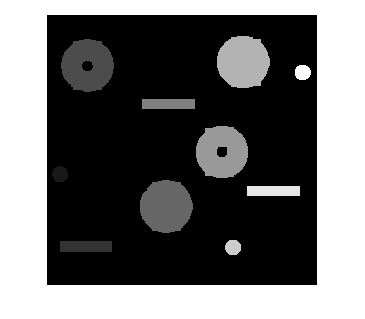

% Labelling 
Image1c_label = bwlabel(Image1c_clean);
imshow(Image1c_label,[]);

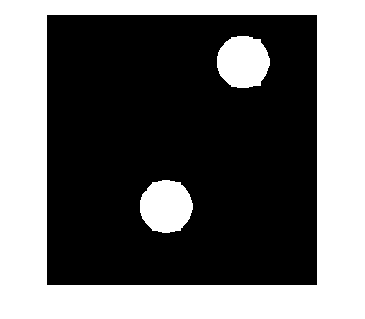


stats = regionprops(logical(Image1c_label),'Area','Perimeter');

for n=1:length(stats)
    Perimeter(n)=stats(n).Perimeter; 
    Area(n)=stats(n).Area;
end

LargeO=find(Area > 7800);
LargeO_Im=zeros(r,c);

for n=1:length(LargeO)
    LargeO_Im(Image1c_label==LargeO(n))=1;
end
imshow(LargeO_Im);

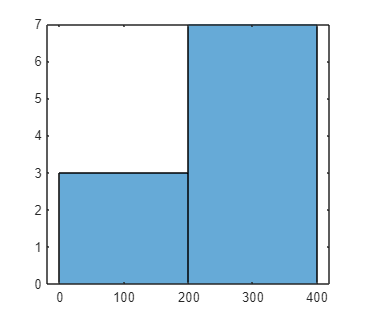


histogram(Perimeter);

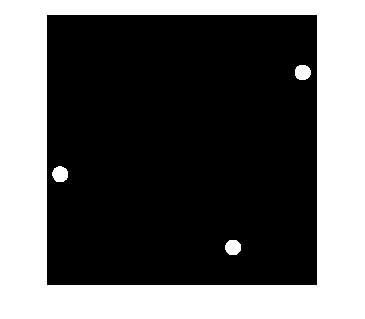


thresh = 100;

SmallO = find(Perimeter<thresh);
SmallO_Im=zeros(r,c);
for n=1:length(SmallO)
    SmallO_Im(Image1c_label==SmallO(n))=1;
end

imshow(SmallO_Im);